clear;
clc;
load('cone_scan2.mat')
vectors = vector_cone

vectors =            0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        3362        3354        3354        3354        3394           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
        1156        1156        1195        1290        1552        1606        1646        1661        1685        1685        1685        1668        1190        1171        1171        1170        1169        1169        1169        1169        1883        1956        1978        1978        1978        2008        2030        2058        2520        2520        2524        2520     

% servo_fit = 
%      Linear model Poly1:
%      servo_fit(x) = p1*x + p2
%      Coefficients (with 95% confidence bounds):
%        p1 =      -1.499  (-1.704, -1.294)
%        p2 =      0.5069  (0.4534, 0.5604)

x = zeros(41,682);
y = zeros(41,682);
z = zeros(41,682);
pan_angles = (-120:240/682:120-240/682)*pi/180;    % Convert sensor steps to angles for plotting
l = 110;

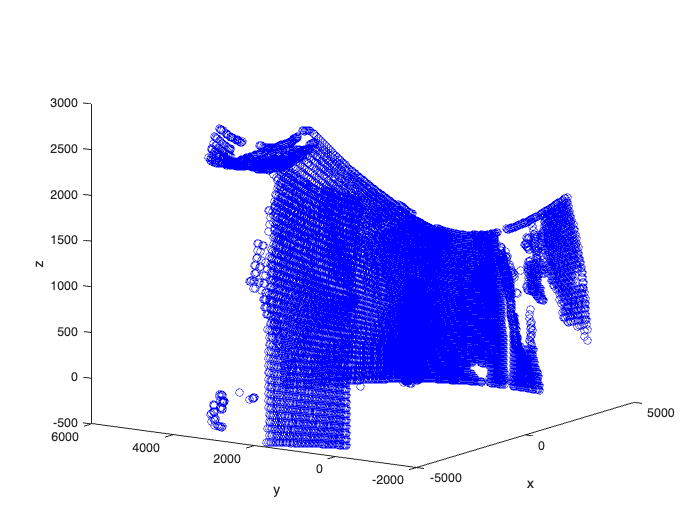

plot3(x,y,z,'o','Color','b')
xlabel('x')
ylabel('y')
zlabel('z')

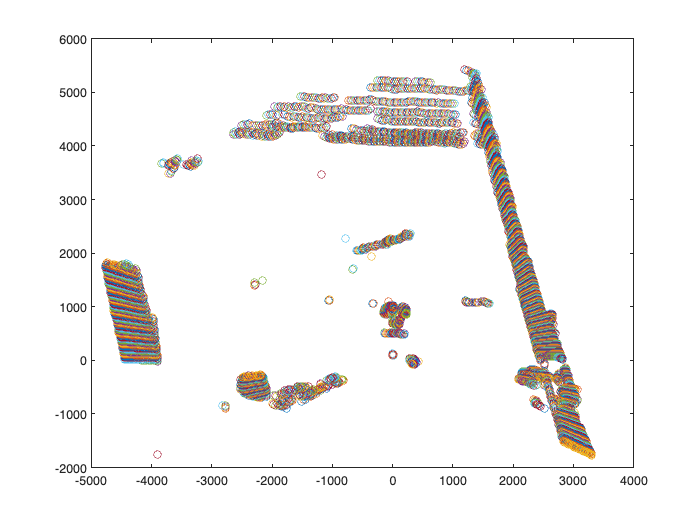

plot(x,y,'o')

vectors = vector_cone;


for (i = 0:39)
    commanded = i/100;
    tilt_angle =  -1.499  * commanded + 0.5069;
    disp(tilt_angle)
     x(i+1,:) = cos(tilt_angle)*vectors(i+1,:).*sin(pan_angles);
     y(i+1,:) = cos(tilt_angle)*vectors(i+1,:).*cos(pan_angles) + l*cos(tilt_angle);
     z(i+1,:) = sin(tilt_angle)*vectors(i+1,:) + l*sin(tilt_angle);

end

    0.5069

    0.4919

    0.4769

    0.4619

    0.4469

    0.4320

    0.4170

    0.4020

    0.3870

    0.3720

    0.3570

    0.3420

    0.3270

    0.3120

    0.2970

    0.2821

    0.2671

    0.2521

    0.2371

    0.2221

    0.2071

    0.1921

    0.1771

    0.1621

    0.1471

    0.1321

    0.1172

    0.1022

    0.0872

    0.0722

    0.0572

    0.0422

    0.0272

    0.0122

   -0.0028

   -0.0178

   -0.0327

   -0.0477

   -0.0627

   -0.0777



x(1,1:3)

ans =      0     0     0


mid = 682/2;
window_size = 200;

x_filter = zeros(41,window_size*2+1);
y_filter = zeros(41,window_size*2+1);
z_filter = zeros(41,window_size*2+1);

for (i=1:41)
    x_filter(i,:) = x(i,mid-window_size:mid+window_size);
    y_filter(i,:) = y(i,mid-window_size:mid+window_size);
    z_filter(i,:) = z(i,mid-window_size:mid+window_size);
end

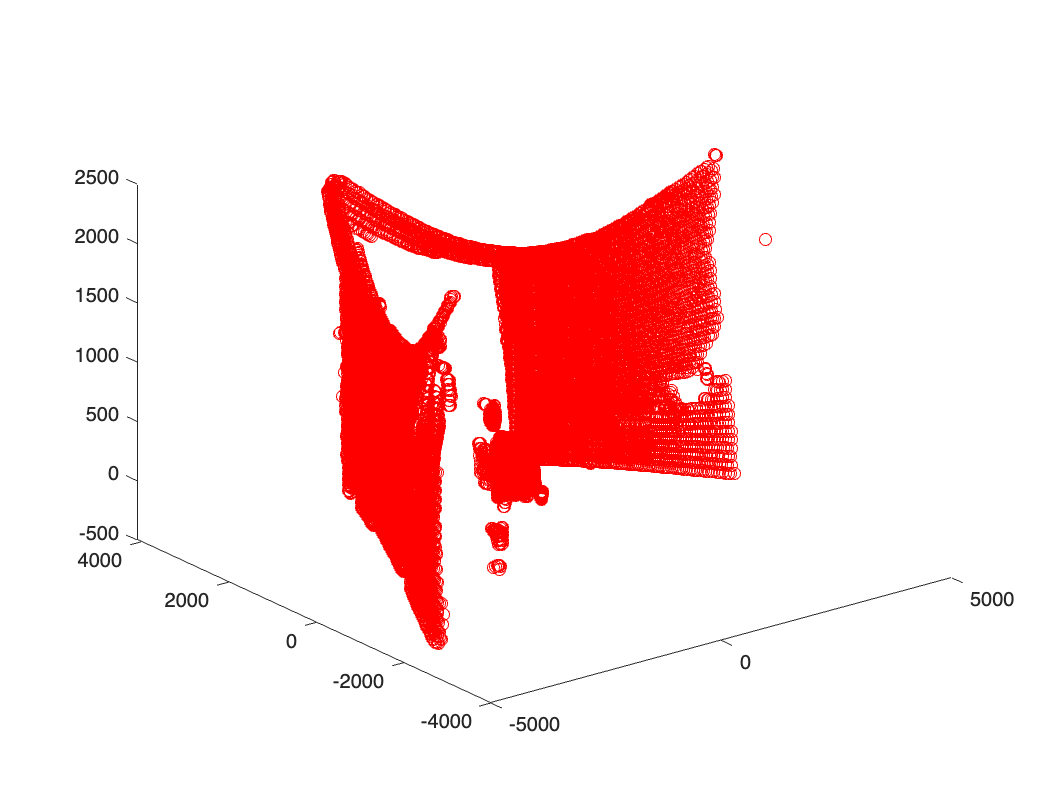

plot3(x,y,z,'o','color','r')

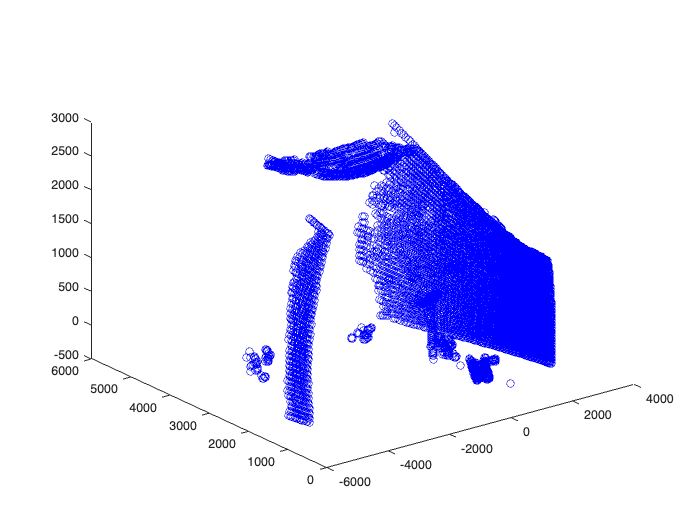

plot3(x_filter,y_filter,z_filter,'o','color','b')

z = sin(tilt_angle)*d;
x = cos(tilt_angle)*sin(pan_angle)*d;
y = cos(tilt_angle)*cos(pan_angle)*d;

x = d*sin(pan_angle)*sin(tilt_angle)-l*cos(tilt_angle);
y = d*sin(pan_angle);
z = l*cos(tilt_angle) + d*sin(tilt_angle)